# **Analyses of collective movements vs. structure and dynamics of the society**

Analyses of movement variables (pair distance and path similarity) of horse pairs, relations between path similarity, distance, kinship, shared past and future (in the same harem) and social levels for the paper

**Fine-scale collective movements reveal present, past and future dynamics of a multilevel society in Przewalski’s horses**

Ozogány, K., Kerekes, V., Fülöp, A., Barta, Z. & Nagy, M., *Nat. Commun.* (2023)

Load the database

load("./data/data.mat")

## **Levels of the society**

% exclude infants
temp = V5pairs(ismember(V5pairs.status1,["af";"hs";"ym";"yf";"ba"]),:);
temp = temp(ismember(temp.status2,["af";"hs";"ym";"yf";"ba"]),:);

#### Single 5-min observation session

temp = temp(strcmp(temp.sample,'V180817'),:);
temp = temp(or(temp.sameharem == 0,temp.sameharem == 1),:);
[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.social_level1,'family')),temp.distance(strcmp(temp.social_level1,'harem')),10000)

dm = -3.8212

p = 2.4452e-07

n1 = 70

n2 = 707

[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.social_level1,'harem')),temp.distance(strcmp(temp.social_level1,'superharem')),10000)

dm = -37.7527

p = 1.0454e-07

n1 = 707

n2 = 20959

[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.social_level1,'superharem')),temp.distance(strcmp(temp.social_level1,'herd')),10000)

dm = -16.9142

p = 2.1222e-07

n1 = 20959

n2 = 8778

[dm,p,n1,n2] = randomisation_meandiff2(temp.Cor(strcmp(temp.social_level1,'family')),temp.Cor(strcmp(temp.social_level1,'harem')),10000)

dm = 0.0338

p = 1.9159e-04

n1 = 70

n2 = 707

[dm,p,n1,n2] = randomisation_meandiff2(temp.Cor(strcmp(temp.social_level1,'harem')),temp.Cor(strcmp(temp.social_level1,'superharem')),10000)

dm = 0.0340

p = 1.2983e-07

n1 = 707

n2 = 20959

[dm,p,n1,n2] = randomisation_meandiff2(temp.Cor(strcmp(temp.social_level1,'superharem')),temp.Cor(strcmp(temp.social_level1,'herd')),10000)

dm = 0.0402

p = 1.4001e-07

n1 = 20959

n2 = 8778

#### Averaged observation sessions

temp = pairs;
temp = temp(ismember(temp.status1,["af";"hs";"ym";"yf";"ba"]),:);
temp = temp(ismember(temp.status2,["af";"hs";"ym";"yf";"ba"]),:);
[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.social_level,'family')),temp.distance(strcmp(temp.social_level,'harem')),10000)

dm = -3.2935

p = 4.7269e-04

n1 = 70

n2 = 711

[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.social_level,'harem')),temp.distance(strcmp(temp.social_level,'herd')),10000)

dm = -58.4776

p = 8.5884e-08

n1 = 711

n2 = 21374

[dm,p,n1,n2] = randomisation_meandiff2(temp.Cor2(strcmp(temp.social_level,'family')),temp.Cor2(strcmp(temp.social_level,'harem')),10000)

dm = 0.0155

p = 1.8314e-05

n1 = 70

n2 = 711

[dm,p,n1,n2] = randomisation_meandiff2(temp.Cor2(strcmp(temp.social_level,'harem')),temp.Cor2(strcmp(temp.social_level,'herd')),10000)

dm = 0.0395

p = 1.3573e-07

n1 = 711

n2 = 21374

## **Society, kinship and familiarity**

#### Network inside harems

Flexible threshold for distances, different d_th in harems: in each harem find the threshold, where all nodes belong to the same connected component.

(exclude females who change harem during observations)

harem changing individuals: ["Kisasszony"; "Nokedli"; "Oda";  "Pinka"; "Ragyog"; "Salomon"; "Seramis"]

Find the flexible threshold for each harem:

G2 = graph();
for i = 1:size(harem_traits2,1)
    k = 0;
    harem = harem_traits2.harem{i};
    members = individuals.name(strcmp(individuals.harem,harem),:);
    % we exclude harem changers
    members = setdiff(members, ["Kisasszony"; "Nokedli"; "Oda";  "Pinka"; "Ragyog"; "Salomon"; "Seramis"]);
    G = graph();
    G = addnode(G,members);
    while max(conncomp(G)) > 1
        k = k + 1;
        temp1 = pairs(and(and(pairs.sameharem==1,pairs.distance<k),strcmp(pairs.harem1,harem)),:);
        G = graph(temp1.name1,temp1.name2);
        temp2 = setdiff(members,G.Nodes.Name);
        G = addnode(G,temp2);
    end
    harem_traits2.flex_dist_th(i) = k;
    G2 = addedge(G2,temp1.name1,temp1.name2,temp1.distance);   
end
temp2 = setdiff(individuals.name,G2.Nodes.Name);
G2 = addnode(G2,temp2);
Gsocnw1_sh = G2;

Plot the network with flexible thresholds:

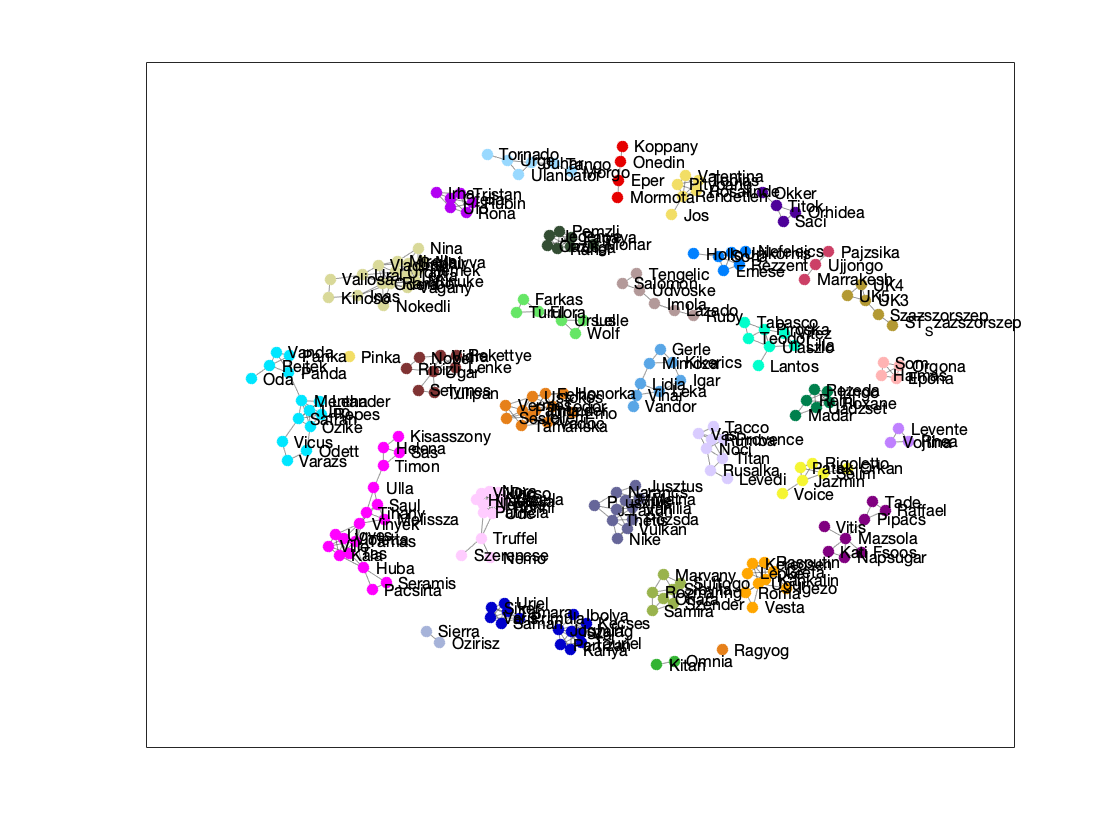

Gsocnw1_sh.Nodes.harem = vlookup(Gsocnw1_sh.Nodes.Name,individuals.name,individuals.harem);
Gsocnw1_sh.Nodes.NodeColor = vlookup(Gsocnw1_sh.Nodes.harem,colors_new.harem,colors_new.cc(:,1:3));
plot(Gsocnw1_sh,'Layout','force','UseGravity',true,'NodeLabel',Gsocnw1_sh.Nodes.Name,'NodeColor',Gsocnw1_sh.Nodes.NodeColor,'MarkerSize',5,'EdgeColor', [0.2,0.2,0.2]);

#### Network between harems

One threshhold which connects all of the harems.

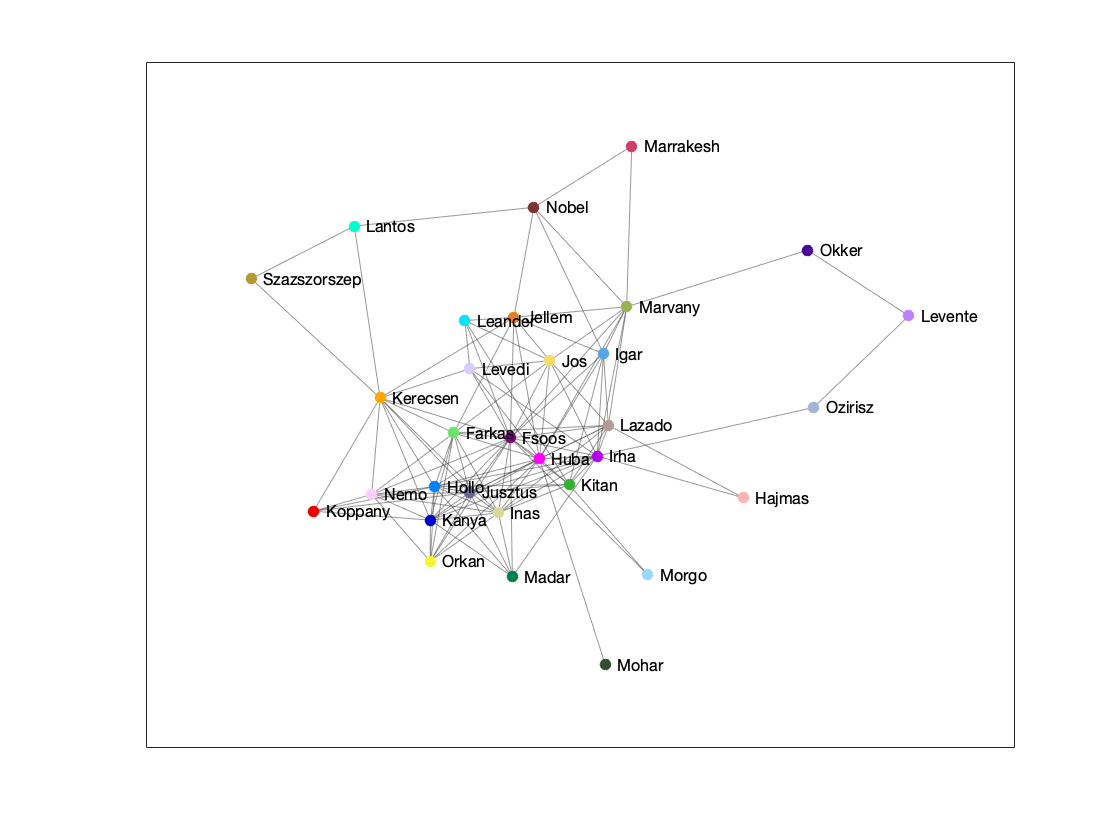

temp1 = pairs(pairs.distance<53,:);
temp2 = temp1(:,{'harem1','harem2'});
temp3 = unique(temp2(:,1:2));
edges = [temp3.harem1 temp3.harem2];
edges = sort(edges')';
temp3.harem1 = edges(:,1);
temp3.harem2 = edges(:,2);
temp3 = unique(temp3(:,1:2));
G2 = graph(temp3.harem1,temp3.harem2,'omitselfloops');
G2.Nodes.NodeColor = vlookup(G2.Nodes.Name,colors_new.harem,colors_new.cc(:,1:3));
plot(G2,'Layout','force','UseGravity',true,'NodeLabel',G2.Nodes.Name,'NodeColor',G2.Nodes.NodeColor,'MarkerSize',5,'EdgeColor', [0.2,0.2,0.2])

Gsocnw1_h = G2;
Gsocnw1_h.Nodes.degree = centrality(Gsocnw1_h,'degree');
Gsocnw1_h.Nodes.closeness = centrality(Gsocnw1_h,'closeness');

#### Network distance of individuals and harems

Shortest path between same harem horse pairs:

pairs_sh = pairs(pairs.sameharem == 1,:);
for i = 1:size(pairs_sh,1)
    [p, pairs_sh.socnw_dist(i)] = shortestpath(Gsocnw1_sh,pairs_sh.name1{i},pairs_sh.name2{i},'Method','unweighted');
end

and different harem horse pairs:

for i = 1:size(harempairs_all,1)
    [p, harempairs_all.socnw_hdist(i)] = shortestpath(Gsocnw1_h,harempairs_all.harem1{i},harempairs_all.harem2{i});
end
pairs_dh = pairs(pairs.sameharem == 0,:);
pairs_dh.socnw_hdist = vlookup(pairs_dh.harem1_harem2,harempairs_all.harem1_harem2,harempairs_all.socnw_hdist);
pairs_afaf = pairs(strcmp(pairs.status_con,"afaf"),:);
pairs_afaf_dh = pairs_afaf(pairs_afaf.sameharem == 0,:);
pairs_afaf_dh.socnw_hdist = vlookup(pairs_afaf_dh.harem1_harem2,harempairs_all.harem1_harem2,harempairs_all.socnw_hdist);
pairs_afaf_sh = pairs_afaf(pairs_afaf.sameharem == 1,:);
pairs_afaf_sh.socnw_dist = vlookup(pairs_afaf_sh.name1_name2,pairs_sh.name1_name2,pairs_sh.socnw_dist);
pairs_hshs.socnw_hdist = vlookup(pairs_hshs.harem1_harem2,harempairs_all.harem1_harem2,harempairs_all.socnw_hdist);

#### Kinship of adult females in the same harem

Full and half-siblings vs non-related

pairs_afaf = pairs(strcmp(pairs.status_con,'afaf'),:);
temp = pairs_afaf_sh(ismember(pairs_afaf_sh.kinship_cat3,["smsf";"sm";"sf";"n"]),:);
temp.kinship_cat3(strcmp(temp.kinship_cat3,'sm')) = {"kin"};
temp.kinship_cat3(strcmp(temp.kinship_cat3,'sf')) = {"kin"};
temp.kinship_cat3(strcmp(temp.kinship_cat3,'smsf')) = {"kin"};
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_dist(strcmp(temp.kinship_cat3,"kin")),temp.socnw_dist(and(strcmp(temp.kinship_cat3,"n"),isfinite(temp.socnw_dist))),10000)

dm = -0.4506

p = 0.0786

n1 = 15

n2 = 199

[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.kinship_cat3,"kin")),temp.distance(strcmp(temp.kinship_cat3,"n")),10000)

dm = -3.2175

p = 0.0919

n1 = 15

n2 = 205

Mother-daughter vs non-related

temp = pairs_afaf_sh(ismember(pairs_afaf_sh.kinship_cat3,["mof";"n"]),:);
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_dist(and(strcmp(temp.kinship_cat3,"mof"),isfinite(temp.socnw_dist))),temp.socnw_dist(and(strcmp(temp.kinship_cat3,"n"),isfinite(temp.socnw_dist))),10000)

dm = -0.2284

p = 0.3345

n1 = 9

n2 = 199

[dm,p,n1,n2] = randomisation_meandiff2(temp.distance(strcmp(temp.kinship_cat3,"mof")),temp.distance(strcmp(temp.kinship_cat3,"n")),10000)

dm = 0.7966

p = 0.3741

n1 = 10

n2 = 205

in the whole population, number of siblings

size(pairs_afaf(ismember(pairs_afaf.kinship_cat3,["smsf";"sm";"sf"]),:),1)

ans = 340

ratio

size(pairs_afaf(ismember(pairs_afaf.kinship_cat3,["smsf";"sm";"sf"]),:),1)./size(pairs_afaf,1)

ans = 0.0519

[dm,p,n1] = randomise_paireddiff(harem_traits2.afaf_siblings_ratio,repmat(340/6555,31,1),10000)

dm = 0.0344

p = 0.1054

n1 = 31

#### Familiarity of adult females in the same harem

temp = pairs_afaf_sh(and(strcmp(pairs_afaf_sh.kinship_cat3,'n'),isfinite(pairs_afaf_sh.socnw_dist)),:);
[r,p,n] = randomise_corr(temp.together_last2y,temp.socnw_dist,10000,'Pearson')

r = -0.1750

p = 0.0077

n = 199

#### Kinship of stallions between harems

Harems of stallions that are close kins (brothers) are closer than the ones of non-related stallions (further relationship).

temp = pairs_hshs(ismember(pairs_hshs.kinship_cat3,["smsf";"sm";"sf";"n"]),:);
temp.kinship_cat3(strcmp(temp.kinship_cat3,'sm')) = 'kin';
temp.kinship_cat3(strcmp(temp.kinship_cat3,'sf')) = 'kin';
temp.kinship_cat3(strcmp(temp.kinship_cat3,'smsf')) = 'kin';
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_hdist(strcmp(temp.kinship_cat3,'kin')),temp.socnw_hdist(strcmp(temp.kinship_cat3,'n')),10000)

dm = -0.3852

p = 6.7248e-04

n1 = 53

n2 = 411

temp = pairs_hshs(ismember(pairs_hshs.kinship_cat3,["smsf";"sm";"sf"]),:);
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_hdist(strcmp(temp.kinship_cat3,'sm')),temp.socnw_hdist(strcmp(temp.kinship_cat3,'sf')),10000)

dm = -0.0500

p = 0.4719

n1 = 4

n2 = 40

temp.kinship_cat3(strcmp(temp.kinship_cat3,'sm')) = 'R25';
temp.kinship_cat3(strcmp(temp.kinship_cat3,'sf')) = 'R25';
temp.kinship_cat3(strcmp(temp.kinship_cat3,'smsf')) = 'R50';
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_hdist(strcmp(temp.kinship_cat3,'R50')),temp.socnw_hdist(strcmp(temp.kinship_cat3,'R25')),10000)

dm = -0.4621

p = 0.0423

n1 = 9

n2 = 44

[r,p,n] = randomise_corr(temp.socnw_hdist,temp.together_past,10000,'Pearson')

r = 0.1676

p = 0.1191

n = 53

[r,p,n] = randomise_corr(temp.hdist,temp.together_past,10000,'Pearson')

r = 0.0630

p = 0.3305

n = 53

#### Kinship of females between harems

temp = harempairs(and(ismember(harempairs.kin_afpairs,["full-sib";"half-sib";"n"]),harempairs.together_last2y_af == 0),:);
temp.kin_afpairs(strcmp(temp.kin_afpairs,"full-sib")) = "sib";
temp.kin_afpairs(strcmp(temp.kin_afpairs,"half-sib")) = "sib";
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_hdist(strcmp(temp.kin_afpairs,'sib')),temp.socnw_hdist(strcmp(temp.kin_afpairs,'n')),10000)

dm = -0.3084

p = 0.0035

n1 = 65

n2 = 206

[dm,p,n1,n2] = randomisation_meandiff2(temp.dist2_V5ave(strcmp(temp.kin_afpairs,'sib')),temp.dist2_V5ave(strcmp(temp.kin_afpairs,'n')),10000)

dm = -1.3050

p = 0.3360

n1 = 65

n2 = 206

temp = harempairs(and(ismember(harempairs.kin_afpairs,["mo-fo";"n"]),harempairs.together_last2y_af == 0),:);
[dm,p,n1,n2] = randomisation_meandiff2(temp.socnw_hdist(strcmp(temp.kin_afpairs,'mo-fo')),temp.socnw_hdist(strcmp(temp.kin_afpairs,'n')),10000)

dm = -0.0985

p = 0.3409

n1 = 14

n2 = 206

[dm,p,n1,n2] = randomisation_meandiff2(temp.dist2_V5ave(strcmp(temp.kin_afpairs,'mo-fo')),temp.dist2_V5ave(strcmp(temp.kin_afpairs,'n')),10000)

dm = 2.1255

p = 0.3561

n1 = 14

n2 = 206

## Group Dynamics

Harems that exchanged members btw 2016-2018 are closer to each other than others.

[dm,p,n1,n2] = randomisation_meandiff2(harempairs.socnw_hdist(harempairs.flow_16_18_br_undir>0),harempairs.socnw_hdist(harempairs.flow_16_18_br_undir==0),10000)

dm = -0.3318

p = 0.0227

n1 = 27

n2 = 438

Harems that exchanged members btw 2018-2020 are closer to each other than others.

[dm,p,n1,n2] = randomisation_meandiff2(harempairs.socnw_hdist(harempairs.flow_18_20_br_undir>0),harempairs.socnw_hdist(harempairs.flow_18_20_br_undir==0),10000)

dm = -0.3588

p = 0.0197

n1 = 24

n2 = 441

Future of females in the same harem

temp = pairs_afaf_sh(and(strcmp(pairs_afaf_sh.kinship_cat3,'n'),isfinite(pairs_afaf_sh.socnw_dist)),:);
[r,p,n] = randomise_corr(temp.together_next2y,temp.socnw_dist,10000,'Pearson')

r = -0.1599

p = 0.0141

n = 199

Future of females in different harems

pairs_afaf_n = pairs(and(strcmp(pairs.status_con,'afaf'),strcmp(pairs.kinship_cat3,'n')),:);
temp = pairs_afaf_n(pairs_afaf_n.sameharem == 0,:);
temp = temp(temp.together_last2y == 0,:);
temp3 = temp(temp.together_next2y>90,:);
%temp = pairs_afaf;
for i = 1:size(temp3,1)
    name12 = temp3.name1_name2{i};
    harem12 = temp3.harem1_harem2{i};
    harem21 = append(temp3.harem2{i},temp3.harem1{i});
    temp1 = temp(strcmp(temp.harem1_harem2,harem12),:);
    temp1 = temp1(not(strcmp(temp1.name1_name2,name12)),:);
    temp2 = temp(strcmp(temp.harem1_harem2,harem21),:);
    temp1 = [temp1;temp2];
    temp1 = temp1(temp1.together_next2y == 0,:);
    temp3.haremcor(i) = nanmean(temp1.Cor2);
end
[h,p] = ttest(temp3.Cor2,temp3.haremcor)

h = 1

p = 0.0233

[dm,p,n1] = randomise_paireddiff(temp3.Cor2,temp3.haremcor,10000)

dm = 0.0044

p = 0.0131

n1 = 107

## Network centrality

#### Centrality vs harem traits

[r,p,n] = randomise_corr(harem_traits2.HS_age_2018,harem_traits2.degree,10000,'pearson')

r = 0.6520

p = 9.1757e-05

n = 30

[r,p,n] = randomise_corr(harem_traits2.HS_age_2018,harem_traits2.closeness,10000,'pearson')

r = 0.6307

p = 9.3551e-05

n = 30

[r,p,n] = randomise_corr(harem_traits2.hs_experience,harem_traits2.degree,10000,'pearson')

r = 0.7157

p = 1.3426e-07

n = 31

[r,p,n] = randomise_corr(harem_traits2.hs_experience,harem_traits2.closeness,10000,'pearson')

r = 0.6626

p = 3.1219e-07

n = 31

[r,p,n] = randomise_corr(harem_traits2.hs_experience,harem_traits2.HS_age_2018,10000,'pearson')

r = 0.8490

p = 1.8132e-07

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremsize_av2018,harem_traits2.degree,10000,'pearson')

r = 0.4724

p = 0.0049

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremsize_av2018,harem_traits2.closeness,10000,'pearson')

r = 0.4679

p = 0.0054

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremsize_av2018,harem_traits2.hs_experience,10000,'pearson')

r = 0.3607

p = 0.0309

n = 31

[r,p,n] = randomise_corr(harem_traits2.no_adults-1,harem_traits2.degree,10000,'pearson')

r = 0.2503

p = 0.0920

n = 31

[r,p,n] = randomise_corr(harem_traits2.no_adults,harem_traits2.closeness,10000,'pearson')

r = 0.2859

p = 0.0638

n = 31

[r,p,n] = randomise_corr(harem_traits2.no_adults,harem_traits2.hs_experience,10000,'pearson')

r = 0.1664

p = 0.1896

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.degree,10000,'pearson')

r = 0.6039

p = 1.2825e-04

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.closeness,10000,'pearson')

r = 0.5995

p = 4.1088e-04

n = 31

#### Correlations of harem traits

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.hs_experience,10000,'pearson')

r = 0.7235

p = 6.5437e-05

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.HS_age_2018,10000,'pearson')

r = 0.6587

p = 9.1889e-05

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.av_age_af,10000,'pearson')

r = 0.5687

p = 6.6930e-04

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.haremsize_av2018,10000,'pearson')

r = 0.5031

p = 0.0038

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.no_adults,10000,'pearson')

r = 0.2677

p = 0.0770

n = 31

[r,p,n] = randomise_corr(harem_traits2.haremage_com_1py_2,harem_traits2.no_subadults+harem_traits2.no_foals,10000,'pearson')

r = 0.5551

p = 0.0020

n = 31

#### Bachelor distance

[r,p,n] = randomise_corr(harem_traits2.closeness,harem_traits2.bach_dist,10000,'Pearson')

r = -0.1329

p = 0.2425

n = 31

[r,p,n] = randomise_corr((harem_traits2.no_adults),harem_traits2.bach_dist,10000,'Pearson')

r = 0.4299

p = 0.0106

n = 31